# 前日までのレーティングから試合結果を予測する

## 2000年以降の全シーズンについて二つのレーティング(Massey，Elo)それぞれで予測し，予測性能を比較する．

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む(prog_NBADataConcatenation.mlxを実行しておく)

load('../data/NBAResults.mat');
seasonStartYearVals=unique(tbl_results.SeasonStartYear);

予測性能を保存する変数を用意する

PredictedMatches=[];    %予測対象の試合数
CorrectsByElo=[];      %Eloで予測した予測正解数
CorrectsByMassey=[];    %Masseyで予測した予測正解数
CorrectsByMassey_HA=[];    %Massey(ホームアドバンテージ考慮)で予測した予測正解数

計算を早くするため，チーム名などを数値に変換しておく

matchData=zeros(size(tbl_results,1),4);
teamNames=unique(tbl_teams.TeamName);
for n1=1:size(tbl_results,1)
    TeamAName=tbl_results.Home(n1);
    TeamBName=tbl_results.Away(n1);
    TeamANum=find(teamNames== TeamAName);
    TeamBNum=find(teamNames== TeamBName);
    matchData(n1,1)=TeamANum;
    matchData(n1,2)=TeamBNum;
    matchData(n1,3)=tbl_results.HomeScore(n1);
    matchData(n1,4)=tbl_results.AwayScore(n1);
end

### Eloレーティングを計算する

- シーズンが変わった時に初期化する

- 予測対象試合でなくても計算しておく(予測対象試合は後で抽出しなおす)

r=zeros(size(teamNames));
EloRatings=zeros(size(matchData,1),2);
K=16;
for n1=1:size(matchData,1)
    if n1>1 && ...
            (tbl_results.SeasonStartYear(n1)>tbl_results.SeasonStartYear(n1-1))
        r=zeros(size(teamNames));
    end

    TeamANum=matchData(n1,1);
    TeamBNum=matchData(n1,2);
    TeamARating=r(TeamANum);
    TeamBRating=r(TeamBNum);
    EloRatings(n1,1)=TeamARating;
    EloRatings(n1,2)=TeamBRating;
    wl=matchData(n1,3)>matchData(n1,4);
    wHat=1/(1+10^(-(TeamARating-TeamBRating)/400));
    r(TeamANum)=r(TeamANum)+K*(wl-wHat);
    r(TeamBNum)=r(TeamBNum)-K*(wl-wHat);

end

Eloレーティングによる予測

PredictionByElo=EloRatings(:,1)>EloRatings(:,2);

### Masseyレーティングを計算する

- シーズンが変わった時に初期化する

- 日付が変わったらMasseyレーティングを計算する

- 予測対象試合でなくても計算しておく(予測対象試合は後で抽出しなおす)

r=zeros(size(teamNames));
r_HA=zeros(size(teamNames));    %ホームアドバンテージを考慮したレーティング
MasseyRatings=zeros(size(matchData,1),2);
tbl_results=sortrows(tbl_results,"Date");

for n1=1:size(tbl_results,1)
    if n1>1 && ...
            (tbl_results.SeasonStartYear(n1)>tbl_results.SeasonStartYear(n1-1))
        r=zeros(size(teamNames));
    end

    if n1>1 && ...
            (tbl_results.Date(n1)>tbl_results.Date(n1-1))
        % 日付が変わったのでMasseyレーティングを算出
        ind = (tbl_results.SeasonStartYear==tbl_results.SeasonStartYear(n1)) ...
            & tbl_results.Date< tbl_results.Date(n1);
        tmpMatchData=matchData(ind,:);
        X=zeros(size(tmpMatchData,1), size(teamNames,1));
        y=zeros(size(tmpMatchData,1),1);
        for n2=1:size(tmpMatchData,1)
            TeamANum=tmpMatchData(n2,1);
            TeamBNum=tmpMatchData(n2,2);
            ScoreDiff=tmpMatchData(n2,3)-tmpMatchData(n2,4);
            X(n2,TeamANum)=1;X(n2,TeamBNum)=-1;
            y(n2)=ScoreDiff;
        end
        r=pinv(X)*y;

        % ホームアドバンテージ考慮のための拡張
        X_HA=[X ones(size(X,1),1)];
        X_HA=[X_HA;ones(1,size(X_HA,2))];
        X_HA(end,end)=0;
        y_HA=[y;0];

        r_HA=pinv(X_HA)*y_HA;

    end

    TeamANum=matchData(n1,1);
    TeamBNum=matchData(n1,2);
    TeamARating=r(TeamANum);
    TeamBRating=r(TeamBNum);
    MasseyRatings(n1,1)=TeamARating;
    MasseyRatings(n1,2)=TeamBRating;

    TeamARating_HA=r_HA(TeamANum);
    TeamBRating_HA=r_HA(TeamBNum);
    MasseyRatings_HA(n1,1)=TeamARating+r_HA(end);
    MasseyRatings_HA(n1,2)=TeamBRating;


end

Masseyレーティングによる予測

PredictionByMassey=MasseyRatings(:,1)>MasseyRatings(:,2);
PredictionByMassey_HA=MasseyRatings_HA(:,1)>MasseyRatings_HA(:,2);

実際の勝敗

ActualWin=matchData(:,3)>matchData(:,4);

シーズン開始年を指定しそれぞれについて集計する．

for seasonStartYearVal=seasonStartYearVals'
    seasonStartYearVal
    ind = tbl_results.SeasonStartYear==seasonStartYearVal;

seasonStartYearVal = 2000

seasonStartYearVal = 2001

seasonStartYearVal = 2002

seasonStartYearVal = 2003

seasonStartYearVal = 2004

seasonStartYearVal = 2005

seasonStartYearVal = 2006

seasonStartYearVal = 2007

seasonStartYearVal = 2008

seasonStartYearVal = 2009

seasonStartYearVal = 2010

seasonStartYearVal = 2011

seasonStartYearVal = 2012

seasonStartYearVal = 2013

seasonStartYearVal = 2014

seasonStartYearVal = 2015

seasonStartYearVal = 2016

seasonStartYearVal = 2017

seasonStartYearVal = 2018

予測対象の開始日を求める

    seasonStartDate=min(tbl_results.Date(ind));
    predictionStartDate=seasonStartDate+days(31);

テスト用(test)の試合結果の表を作る

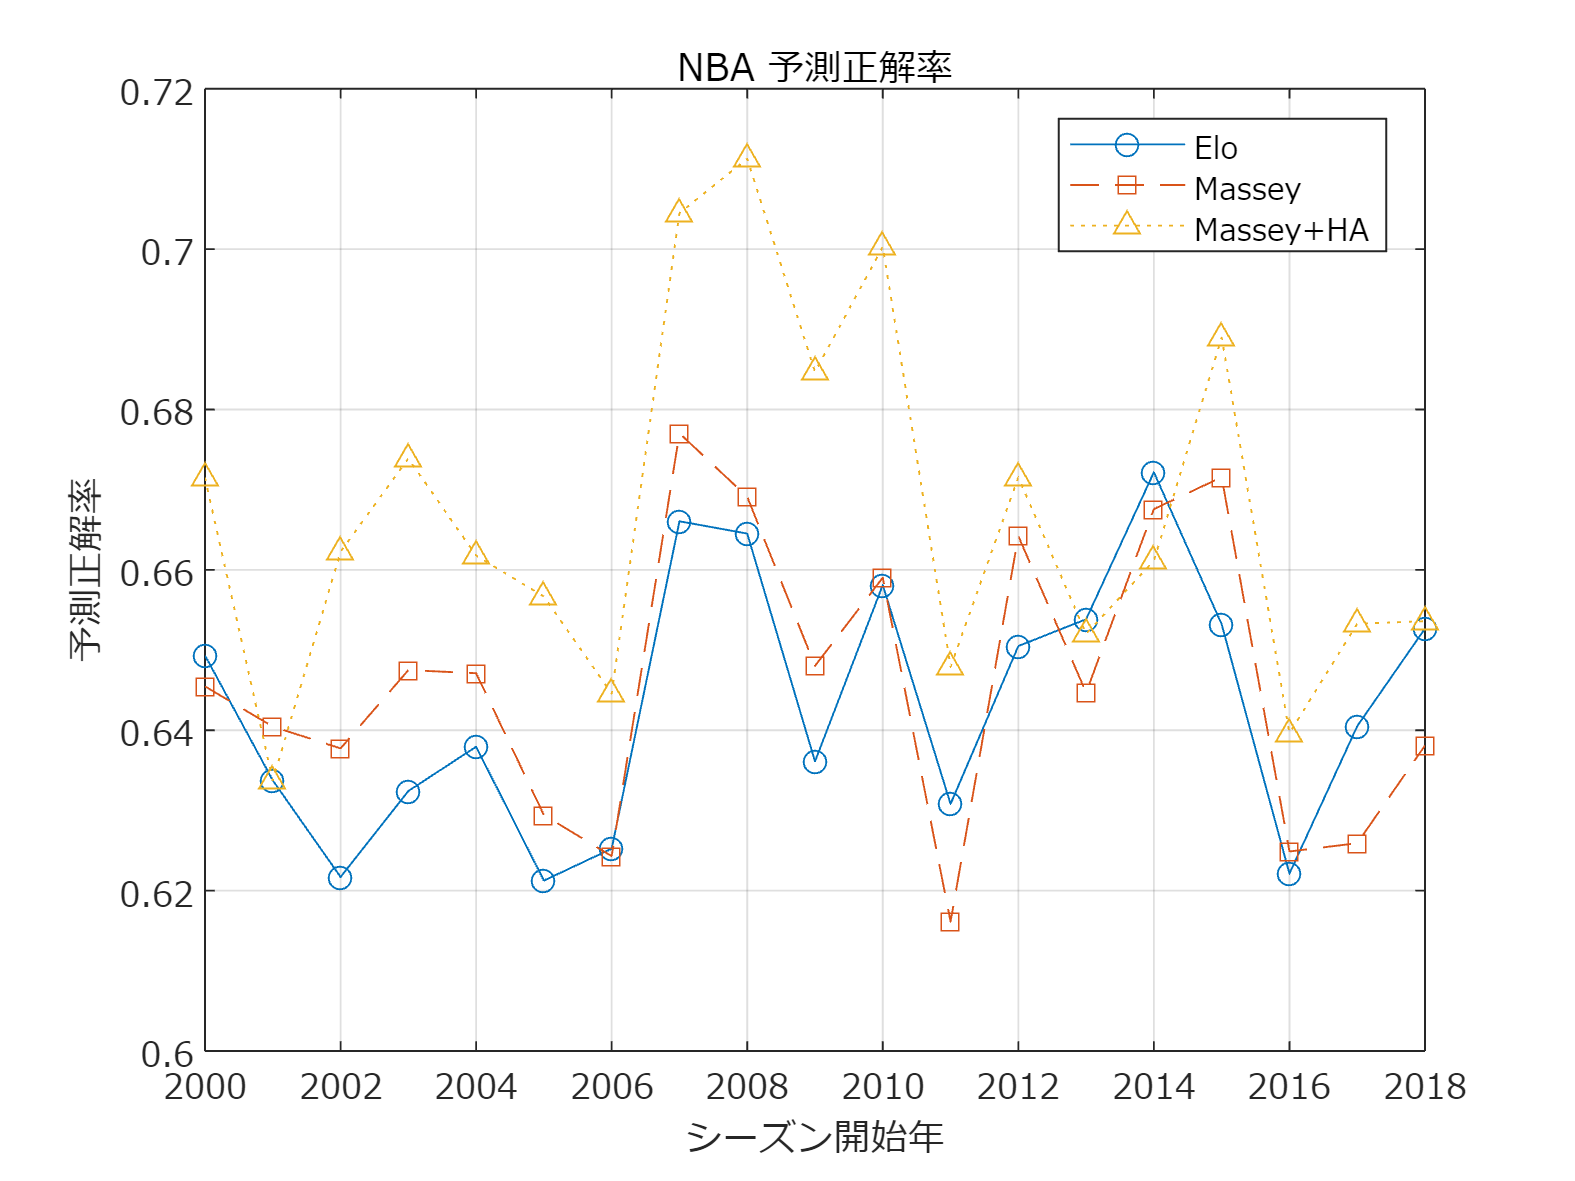

    ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
        & tbl_results.Date>=predictionStartDate;

    PredictedMatches=[PredictedMatches;sum(ind)];
    CorrectsByElo=[CorrectsByElo;...
        sum(PredictionByElo(ind)==ActualWin(ind))];
    CorrectsByMassey=[CorrectsByMassey;...
        sum(PredictionByMassey(ind)==ActualWin(ind))];
    CorrectsByMassey_HA=[CorrectsByMassey_HA;...

        sum(PredictionByMassey_HA(ind)==ActualWin(ind))];
end

図示する

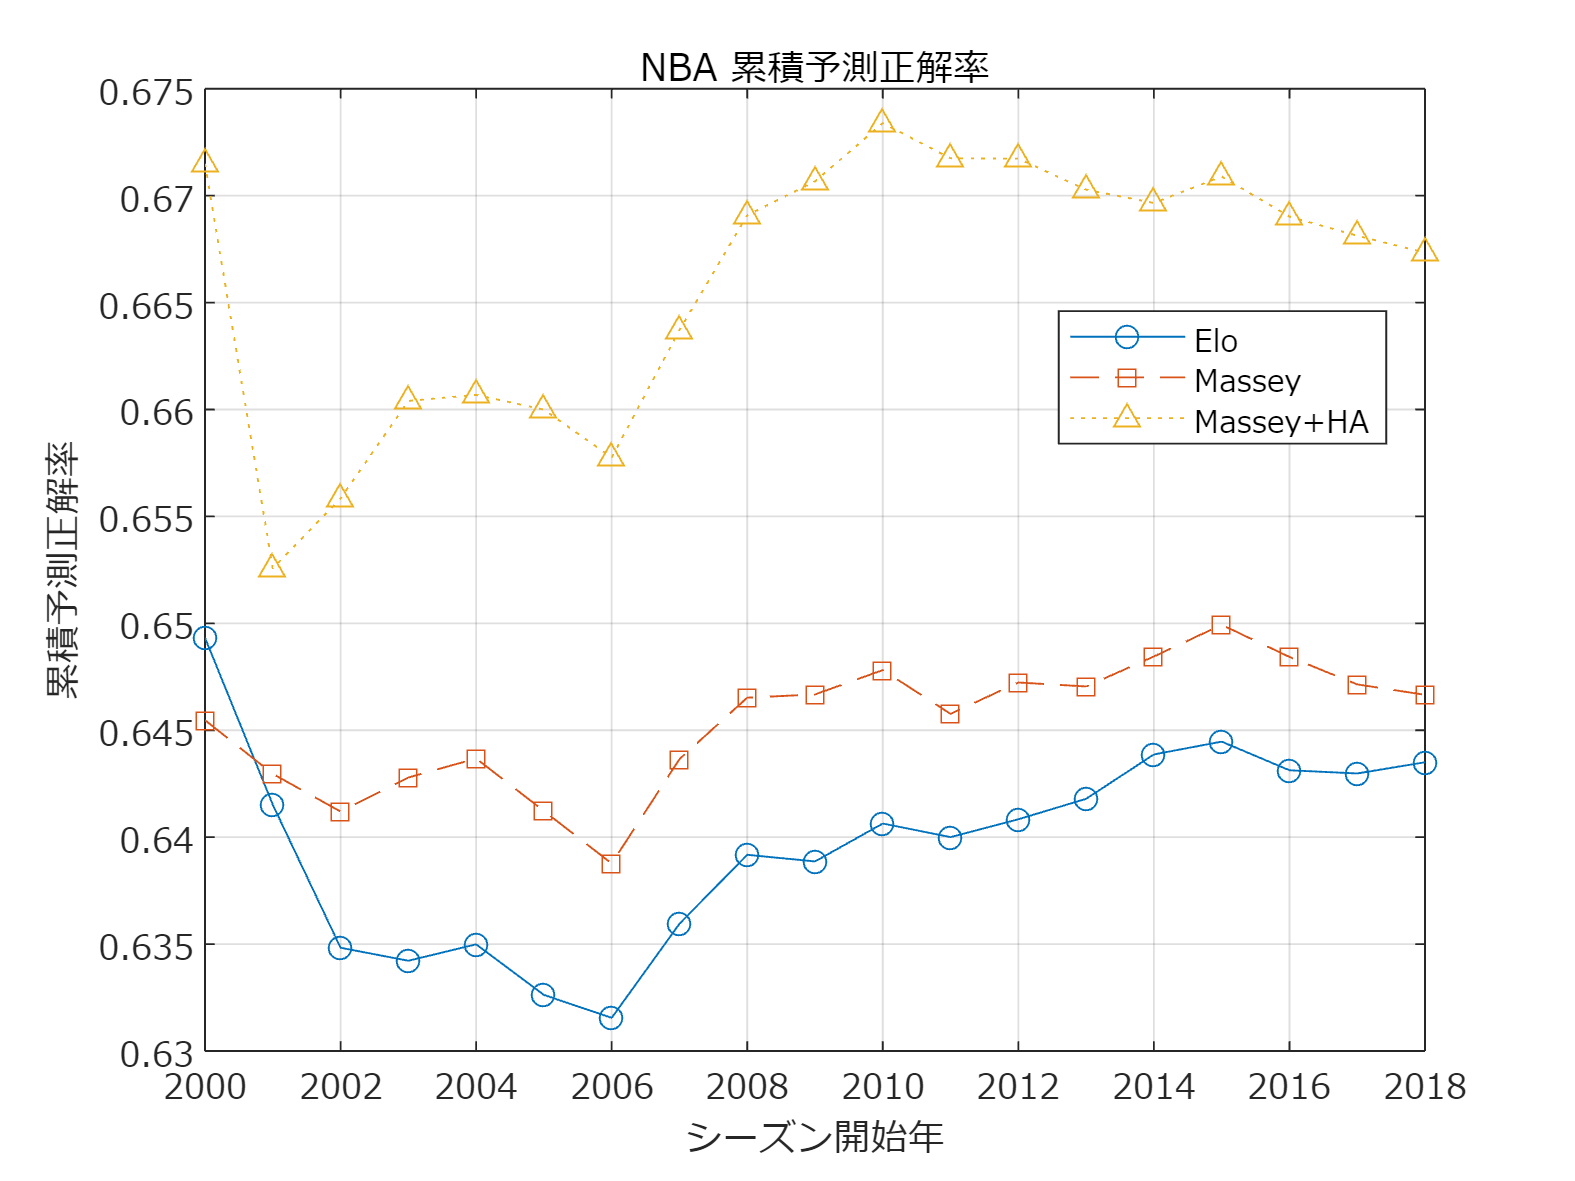

figure;
plot(seasonStartYearVals, CorrectsByElo./PredictedMatches,'o-');
hold on;grid on;
plot(seasonStartYearVals, CorrectsByMassey./PredictedMatches,'s--');
plot(seasonStartYearVals, CorrectsByMassey_HA./PredictedMatches,'^:');

set(gca,'fontname','メイリオ');
xlabel('シーズン開始年');ylabel('予測正解率');
legend({'Elo','Massey','Massey+HA'},'Location','best');

title('NBA 予測正解率');
exportgraphics(gcf,'fig_NBAPredictionByPairwiseByDate.pdf');
figure;
plot(seasonStartYearVals,cumsum(CorrectsByElo)./cumsum(PredictedMatches),'o-');
hold on;grid on;
plot(seasonStartYearVals, cumsum(CorrectsByMassey)./cumsum(PredictedMatches),'s--');
plot(seasonStartYearVals, cumsum(CorrectsByMassey_HA)./cumsum(PredictedMatches),'^:');

set(gca,'fontname','メイリオ');
xlabel('シーズン開始年');ylabel('累積予測正解率');
legend({'Elo','Massey','Massey+HA'},'Location','best');
title('NBA 累積予測正解率');
exportgraphics(gcf,'fig_NBAPredictionCumSumByPairwiseByDate.pdf');